# Machine Learning: Programming Exercise 1

## Linear Regression

In this exercise, you will implement linear regression and get to see it work on data.

## Files needed for this exercise

- `ex1.mlx` - MATLAB Live Script that steps you through the exercise

- `ex1.m, ex1_multi.m` - MATLAB scripts that step you through the exercise. (Not needed if using `ex1.mlx.)`

- ex1data1.txt - Dataset for linear regression with one variable

- ex1data2.txt - Dataset for linear regression with multiple variables

- `submit.m` - Submission script that sends your solutions to our servers

- *`warmUpExercise.m` - Simple example function in MATLAB

- *`plotData.m` - Function to display the dataset

- *`computeCost.m` - Function to compute the cost of linear regression

- *`gradientDescent.m` - Function to run gradient descent

- **`computeCostMulti.m` - Cost function for multiple variables

- **`gradientDescentMulti.m` - Gradient descent for multiple variables

- **`featureNormalize.m `- Function to normalize features

- **`normalEqn.m` - Function to compute the normal equations

****indicates files you will need to complete***

*****indicates optional exercises***

## Setting up your environment

The commands below to clear your workspace of existing variables, display your current directory, and list the files in your current directory. To run the code inside of a MATLAB Live Script section:

- Click into the section to make it active. A blue bar will appear on the left.

- Click either the **Run Section (CTRL+ENTER)** or **Run and Advance (CTRL+SHIFT+ENTER) **buttons in the **Live Editor** tab above. Alternatively, you can click on the blue bar.

In general you will only need to run the commands inside the Live Scripts and not in the command window, except when submitting the exercise files. After running this section, you should see all of the files below listed. 

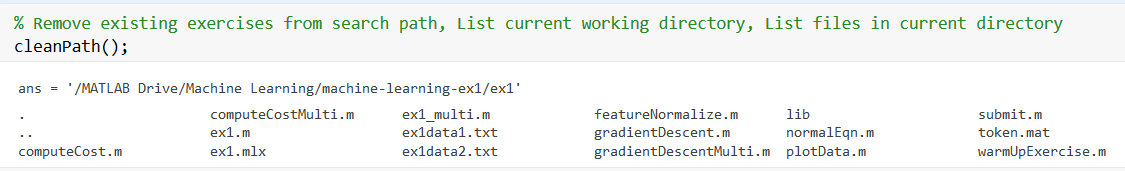

If they are not, change your Current Folder to the **ex1** exercise folder (right-click the ex1 folder and select 'Open'). 

% Clear existing variables
clear;
% Remove existing exercises from search path, list current working directory, and list files in current directory
cleanPath();

ans = '/MATLAB Drive/Published/machine-learning-ex1/ex1'


.                       computeCostMulti.m      ex1_multi.m             featureNormalize.m      lib                     submit.m                
..                      ex1.m                   ex1data1.txt            gradientDescent.m       normalEqn.m             warmUpExercise.m        
computeCost.m           ex1.mlx                 ex1data2.txt            gradientDescentMulti.m  plotData.m              



Note that:

- You may have to reset your Current Folder to the exercise folder after logging out of MATLAB Online.

- The **Run All** and **Run to End** buttons are not recommended for use in these exercises. 

- Executing the Live Script from the command line is also not recommended. 

- You may have to rerun one or more sections after adressing errors in your code or after clearing the workspace variables.

# 1. A simple MATLAB function

The first part of this script gives you practice with MATLAB syntax and the homework submission process. In the file `warmUpExercise.m`, you will find the outline of a MATLAB function. Modify it to return a 5 x 5 identity matrix by filling in the following code:

A = eye(5);

When you are finished, save `warmUpExercise.m`, then run the code contained in this section to call `warmUpExercise().` 

**5x5 Identity Matrix:**

warmUpExercise()

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


You should see output similar to the following:

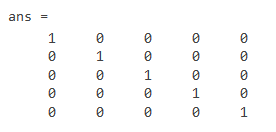

You can toggle between right-hand-side output and in-line output for printing results and displaying figures inside a Live Script by selecting the appropriate box in the upper right of the Live Editor window. 

## 1.1 Submitting Solutions

After completing a part of the exercise, you can submit your solutions for that section by running the section of code below, which calls the `submit.m` script. Your score for each section will then be displayed as output. **Enter your login and your unique submission token *****inside the command window***** when prompted. For future submissions of this exercise, you will only be asked to confirm your credentials.** Your submission token for each exercise is found in the corresponding homework assignment course page. New tokens can be generated if you are experiencing issues with your current token. You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter your login and token when prompted.*

# 2. Linear regression with one variable

In this part of this exercise, you will implement linear regression with one variable to predict profits for a food truck. Suppose you are the CEO of a restaurant franchise and are considering different cities for opening a new outlet. The chain already has trucks in various cities and you have data for profits and populations from the cities. You would like to use this data to help you select which city to expand to next.

The file `ex1data1.txt` contains the dataset for our linear regression problem. The first column is the population of a city and the second column is the profit of a food truck in that city. A negative value for profit indicates a loss. This script has already been set up to load this data for you.

## 2.1 Plotting the data

Before starting on any task, it is often useful to understand the data by visualizing it. For this dataset, you can use a scatter plot to visualize the data, since it has only two properties to plot (profit and population). Many other problems that you will encounter in real life are multi-dimensional and can't be plotted on a 2-d plot.

Run the code below to load the dataset from the data file into the variables X and y:

data = load('ex1data1.txt'); % read comma separated data
X = data(:, 1); y = data(:, 2);

Your job is to complete `plotData.m` to draw the plot; modify the file and fill in the following code:

Once you are finished, save `plotData.m,` and execute the code in this section which will call `plotData`. 

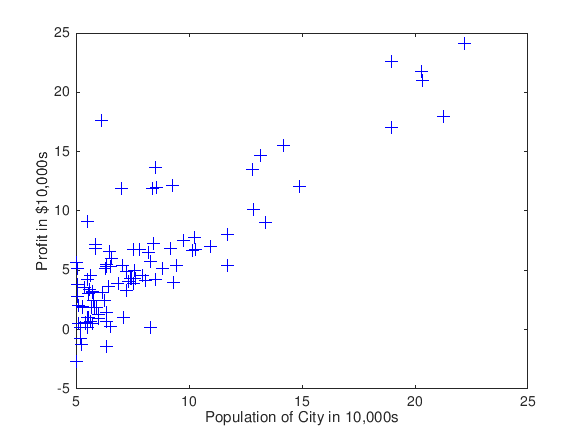

plotData(X,y)

The resulting plot should appear as in Figure 1 below:

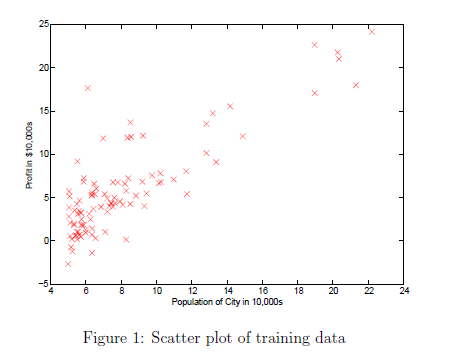

To learn more about the `plot` command, you can run the command `help plot` at the command prompt, type `plot()` inside the MATLAB Live Editor and click on the "(?)" tooltip, or you can search the [MATLAB documentation](https://www.mathworks.com/help/matlab/) for "plot". Note that to change the markers to red x's in the plot, we used the option: **'**`rx'` together with the `plot` command, i.e., 

# 2.2 Gradient Descent

In this section, you will fit the linear regression parameters to our dataset using gradient descent.

## 2.2.1 Update Equations

The objective of linear regression is to minimize the cost function


$$J\left(\theta \right)=\frac{1}{2m}\sum_{i=1}^{m} {\left(h_{\theta \text{ }} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \text{ }$$


where the hypothesis $h_{\theta}(x)$ is given by the linear model


$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


Recall that the parameters of your model are the $\theta$ values. These are the values you will adjust to minimize cost $J(\theta)$. One way to do this is to use the batch gradient descent algorithm. In batch gradient descent, each iteration performs the update


$$\theta_j :=\theta_j -\alpha \frac{\text{ }1}{m}\sum_{i=1}^{m} \text{ }\left(h_{\theta \text{ }} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \text{       }\left(\mathrm{simultaneously}\text{ }\mathrm{update}\text{ }\theta_{j\text{ }} \text{ }\mathrm{for}\text{ }\mathrm{all}\text{ }j\right)$$


With each step of gradient descent, your parameters $j$ come closer to the optimal values that will achieve the lowest cost $J(\theta)$.

**Implementation Note:** We store each example as a row in the the `X` matrix in MATLAB. To take into account the intercept term ($\theta_0$), we add an additional first column to `X` and set it to all ones. This allows us to treat $\theta_0$ as simply another 'feature'.

## 2.2.2 Implementation

In this script, we have already set up the data for linear regression. In the following lines, we add another dimension to our data to accommodate the $\theta_0$ intercept term. Run the code below to initialize the parameters to 0 and the learning rate `alpha` to 0.01. 

m = length(X) % number of training examples

m = 97

X = [ones(m, 1), data(:,1)]; % Add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters
iterations = 1500;
alpha = 0.01;

## 2.2.3 Computing the cost $\mathbf{J}\left(\theta \right)$

As you perform gradient descent to minimize the cost function $J\left(\theta \right)$, it is helpful to monitor the convergence by computing the cost. In this section, you will implement a function to calculate $J\left(\theta \right)$ so you can check the convergence of your gradient descent implementation.

    Your next task is to complete the code in the file `computeCost.m`, which is a function that computes $J\left(\theta \right)$. As you are doing this, remember that the variables `X` and `y` are not scalar values, but matrices whose rows represent the examples from the training set.

    Once you have completed the function definition, run this section. The code below will call `computeCost` once using $\theta$ initialized to zeros, and you will see the cost printed to the screen. You should expect to see a cost of 32.07.

% Compute and display initial cost
computeCost(X, y, theta)

Undefined function or variable 'X'.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## 2.2.4 Gradient descent

Next, you will implement gradient descent in the file `gradientDescent.m`. The loop structure has been written for you, and you only need to supply the updates to $\theta$ within each iteration.

    As you program, make sure you understand what you are trying to optimize and what is being updated. Keep in mind that the cost $J\left(\theta \right)$ is parameterized by the vector $\theta$, not $X$ and $y$. That is, we minimize the value of $J\left(\theta \right)$ by changing the values of the vector $\theta$, not by changing $X$ or $y$. Refer to the equations given earlier and to the video lectures if you are uncertain.

A good way to verify that gradient descent is working correctly is to look at the value of `J` and check that it is decreasing with each step. The starter code for `gradientDescent.m` calls `computeCost` on every iteration and prints the cost. Assuming you have implemented gradient descent and `computeCost` correctly, your value of $J\left(\theta \right)$ should never increase, and should converge to a steady value by the end of the algorithm.

    After you are finished, run this execute this section. The code below will use your final parameters to plot the linear fit. The result should look something like Figure 2 below:

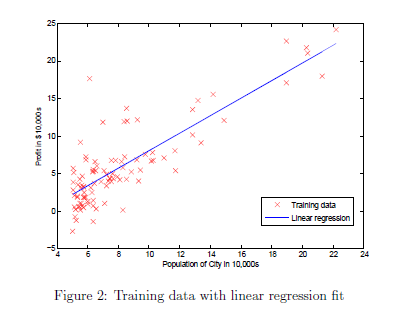    

    Your final values for $\theta$ will also be used to make predictions on profits in areas of 35,000 and 70,000 people.

% Run gradient descent:
% Compute theta
[theta, J_history]= gradientDescent(X, y, theta, alpha, iterations);

cost = 6.7372

cost = 5.9316

cost = 5.9012

cost = 5.8952

cost = 5.8901

cost = 5.8850

cost = 5.8799

cost = 5.8749

cost = 5.8698

cost = 5.8648

cost = 5.8598

cost = 5.8548

cost = 5.8499

cost = 5.8449

cost = 5.8400

cost = 5.8351

cost = 5.8302

cost = 5.8253

cost = 5.8205

cost = 5.8156

cost = 5.8108

cost = 5.8060

cost = 5.8012

cost = 5.7965

cost = 5.7917

cost = 5.7870

cost = 5.7822

cost = 5.7775

cost = 5.7729

cost = 5.7682

cost = 5.7635

cost = 5.7589

cost = 5.7543

cost = 5.7497

cost = 5.7451

cost = 5.7405

cost = 5.7360

cost = 5.7315

cost = 5.7269

cost = 5.7224

cost = 5.7179

cost = 5.7135

cost = 5.7090

cost = 5.7046

cost = 5.7002

cost = 5.6958

cost = 5.6914

cost = 5.6870

cost = 5.6826

cost = 5.6783

cost = 5.6740

cost = 5.6697

cost = 5.6654

cost = 5.6611

cost = 5.6568

cost = 5.6526

cost = 5.6483

cost = 5.6441

cost = 5.6399

cost = 5.6357

cost = 5.6315

cost = 5.6274

cost = 5.6232

cost = 5.6191

cost = 5.6150

cost = 5.6109

cost = 5.6068

cost = 5.6027

cost = 5.5987

cost = 5.5946

cost = 5.5906

cost = 5.5866

cost = 5.5826

cost = 5.5786

cost = 5.5747

cost = 5.5707

cost = 5.5668

cost = 5.5628

cost = 5.5589

cost = 5.5550

cost = 5.5512

cost = 5.5473

cost = 5.5434

cost = 5.5396

cost = 5.5358

cost = 5.5319

cost = 5.5281

cost = 5.5244

cost = 5.5206

cost = 5.5168

cost = 5.5131

cost = 5.5094

cost = 5.5056

cost = 5.5019

cost = 5.4982

cost = 5.4946

cost = 5.4909

cost = 5.4872

cost = 5.4836

cost = 5.4800

cost = 5.4764

cost = 5.4728

cost = 5.4692

cost = 5.4656

cost = 5.4620

cost = 5.4585

cost = 5.4550

cost = 5.4514

cost = 5.4479

cost = 5.4444

cost = 5.4409

cost = 5.4375

cost = 5.4340

cost = 5.4306

cost = 5.4271

cost = 5.4237

cost = 5.4203

cost = 5.4169

cost = 5.4135

cost = 5.4101

cost = 5.4068

cost = 5.4034

cost = 5.4001

cost = 5.3968

cost = 5.3935

cost = 5.3902

cost = 5.3869

cost = 5.3836

cost = 5.3803

cost = 5.3771

cost = 5.3738

cost = 5.3706

cost = 5.3674

cost = 5.3642

cost = 5.3610

cost = 5.3578

cost = 5.3546

cost = 5.3515

cost = 5.3483

cost = 5.3452

cost = 5.3420

cost = 5.3389

cost = 5.3358

cost = 5.3327

cost = 5.3296

cost = 5.3266

cost = 5.3235

cost = 5.3205

cost = 5.3174

cost = 5.3144

cost = 5.3114

cost = 5.3084

cost = 5.3054

cost = 5.3024

cost = 5.2994

cost = 5.2965

cost = 5.2935

cost = 5.2906

cost = 5.2876

cost = 5.2847

cost = 5.2818

cost = 5.2789

cost = 5.2760

cost = 5.2731

cost = 5.2703

cost = 5.2674

cost = 5.2646

cost = 5.2617

cost = 5.2589

cost = 5.2561

cost = 5.2533

cost = 5.2505

cost = 5.2477

cost = 5.2449

cost = 5.2422

cost = 5.2394

cost = 5.2367

cost = 5.2339

cost = 5.2312

cost = 5.2285

cost = 5.2258

cost = 5.2231

cost = 5.2204

cost = 5.2177

cost = 5.2150

cost = 5.2124

cost = 5.2097

cost = 5.2071

cost = 5.2045

cost = 5.2018

cost = 5.1992

cost = 5.1966

cost = 5.1940

cost = 5.1915

cost = 5.1889

cost = 5.1863

cost = 5.1838

cost = 5.1812

cost = 5.1787

cost = 5.1762

cost = 5.1736

cost = 5.1711

cost = 5.1686

cost = 5.1661

cost = 5.1637

cost = 5.1612

cost = 5.1587

cost = 5.1563

cost = 5.1538

cost = 5.1514

cost = 5.1489

cost = 5.1465

cost = 5.1441

cost = 5.1417

cost = 5.1393

cost = 5.1369

cost = 5.1346

cost = 5.1322

cost = 5.1298

cost = 5.1275

cost = 5.1251

cost = 5.1228

cost = 5.1205

cost = 5.1181

cost = 5.1158

cost = 5.1135

cost = 5.1112

cost = 5.1090

cost = 5.1067

cost = 5.1044

cost = 5.1022

cost = 5.0999

cost = 5.0977

cost = 5.0954

cost = 5.0932

cost = 5.0910

cost = 5.0888

cost = 5.0866

cost = 5.0844

cost = 5.0822

cost = 5.0800

cost = 5.0778

cost = 5.0757

cost = 5.0735

cost = 5.0714

cost = 5.0692

cost = 5.0671

cost = 5.0650

cost = 5.0628

cost = 5.0607

cost = 5.0586

cost = 5.0565

cost = 5.0544

cost = 5.0524

cost = 5.0503

cost = 5.0482

cost = 5.0462

cost = 5.0441

cost = 5.0421

cost = 5.0400

cost = 5.0380

cost = 5.0360

cost = 5.0340

cost = 5.0320

cost = 5.0300

cost = 5.0280

cost = 5.0260

cost = 5.0240

cost = 5.0220

cost = 5.0201

cost = 5.0181

cost = 5.0162

cost = 5.0142

cost = 5.0123

cost = 5.0104

cost = 5.0085

cost = 5.0065

cost = 5.0046

cost = 5.0027

cost = 5.0008

cost = 4.9989

cost = 4.9971

cost = 4.9952

cost = 4.9933

cost = 4.9915

cost = 4.9896

cost = 4.9878

cost = 4.9859

cost = 4.9841

cost = 4.9823

cost = 4.9805

cost = 4.9786

cost = 4.9768

cost = 4.9750

cost = 4.9732

cost = 4.9714

cost = 4.9697

cost = 4.9679

cost = 4.9661

cost = 4.9644

cost = 4.9626

cost = 4.9609

cost = 4.9591

cost = 4.9574

cost = 4.9556

cost = 4.9539

cost = 4.9522

cost = 4.9505

cost = 4.9488

cost = 4.9471

cost = 4.9454

cost = 4.9437

cost = 4.9420

cost = 4.9404

cost = 4.9387

cost = 4.9370

cost = 4.9354

cost = 4.9337

cost = 4.9321

cost = 4.9304

cost = 4.9288

cost = 4.9272

cost = 4.9255

cost = 4.9239

cost = 4.9223

cost = 4.9207

cost = 4.9191

cost = 4.9175

cost = 4.9159

cost = 4.9144

cost = 4.9128

cost = 4.9112

cost = 4.9096

cost = 4.9081

cost = 4.9065

cost = 4.9050

cost = 4.9034

cost = 4.9019

cost = 4.9004

cost = 4.8989

cost = 4.8973

cost = 4.8958

cost = 4.8943

cost = 4.8928

cost = 4.8913

cost = 4.8898

cost = 4.8883

cost = 4.8868

cost = 4.8854

cost = 4.8839

cost = 4.8824

cost = 4.8810

cost = 4.8795

cost = 4.8781

cost = 4.8766

cost = 4.8752

cost = 4.8738

cost = 4.8723

cost = 4.8709

cost = 4.8695

cost = 4.8681

cost = 4.8667

cost = 4.8653

cost = 4.8639

cost = 4.8625

cost = 4.8611

cost = 4.8597

cost = 4.8583

cost = 4.8569

cost = 4.8556

cost = 4.8542

cost = 4.8528

cost = 4.8515

cost = 4.8501

cost = 4.8488

cost = 4.8475

cost = 4.8461

cost = 4.8448

cost = 4.8435

cost = 4.8422

cost = 4.8408

cost = 4.8395

cost = 4.8382

cost = 4.8369

cost = 4.8356

cost = 4.8343

cost = 4.8330

cost = 4.8318

cost = 4.8305

cost = 4.8292

cost = 4.8279

cost = 4.8267

cost = 4.8254

cost = 4.8242

cost = 4.8229

cost = 4.8217

cost = 4.8204

cost = 4.8192

cost = 4.8180

cost = 4.8167

cost = 4.8155

cost = 4.8143

cost = 4.8131

cost = 4.8119

cost = 4.8107

cost = 4.8094

cost = 4.8083

cost = 4.8071

cost = 4.8059

cost = 4.8047

cost = 4.8035

cost = 4.8023

cost = 4.8012

cost = 4.8000

cost = 4.7988

cost = 4.7977

cost = 4.7965

cost = 4.7954

cost = 4.7942

cost = 4.7931

cost = 4.7919

cost = 4.7908

cost = 4.7897

cost = 4.7885

cost = 4.7874

cost = 4.7863

cost = 4.7852

cost = 4.7841

cost = 4.7830

cost = 4.7819

cost = 4.7808

cost = 4.7797

cost = 4.7786

cost = 4.7775

cost = 4.7764

cost = 4.7753

cost = 4.7743

cost = 4.7732

cost = 4.7721

cost = 4.7711

cost = 4.7700

cost = 4.7689

cost = 4.7679

cost = 4.7668

cost = 4.7658

cost = 4.7648

cost = 4.7637

cost = 4.7627

cost = 4.7617

cost = 4.7606

cost = 4.7596

cost = 4.7586

cost = 4.7576

cost = 4.7566

cost = 4.7556

cost = 4.7546

cost = 4.7536

cost = 4.7526

cost = 4.7516

cost = 4.7506

cost = 4.7496

cost = 4.7486

cost = 4.7476

cost = 4.7467

cost = 4.7457

cost = 4.7447

cost = 4.7438

cost = 4.7428

cost = 4.7418

cost = 4.7409

cost = 4.7399

cost = 4.7390

cost = 4.7380

cost = 4.7371

cost = 4.7362

cost = 4.7352

cost = 4.7343

cost = 4.7334

cost = 4.7325

cost = 4.7315

cost = 4.7306

cost = 4.7297

cost = 4.7288

cost = 4.7279

cost = 4.7270

cost = 4.7261

cost = 4.7252

cost = 4.7243

cost = 4.7234

cost = 4.7225

cost = 4.7216

cost = 4.7207

cost = 4.7199

cost = 4.7190

cost = 4.7181

cost = 4.7173

cost = 4.7164

cost = 4.7155

cost = 4.7147

cost = 4.7138

cost = 4.7130

cost = 4.7121

cost = 4.7113

cost = 4.7104

cost = 4.7096

cost = 4.7087

cost = 4.7079

cost = 4.7071

cost = 4.7062

cost = 4.7054

cost = 4.7046

cost = 4.7038

cost = 4.7030

cost = 4.7021

cost = 4.7013

cost = 4.7005

cost = 4.6997

cost = 4.6989

cost = 4.6981

cost = 4.6973

cost = 4.6965

cost = 4.6957

cost = 4.6949

cost = 4.6942

cost = 4.6934

cost = 4.6926

cost = 4.6918

cost = 4.6910

cost = 4.6903

cost = 4.6895

cost = 4.6887

cost = 4.6880

cost = 4.6872

cost = 4.6865

cost = 4.6857

cost = 4.6850

cost = 4.6842

cost = 4.6835

cost = 4.6827

cost = 4.6820

cost = 4.6812

cost = 4.6805

cost = 4.6798

cost = 4.6790

cost = 4.6783

cost = 4.6776

cost = 4.6769

cost = 4.6761

cost = 4.6754

cost = 4.6747

cost = 4.6740

cost = 4.6733

cost = 4.6726

cost = 4.6719

cost = 4.6712

cost = 4.6705

cost = 4.6698

cost = 4.6691

cost = 4.6684

cost = 4.6677

cost = 4.6670

cost = 4.6663

cost = 4.6656

cost = 4.6650

cost = 4.6643

cost = 4.6636

cost = 4.6629

cost = 4.6623

cost = 4.6616

cost = 4.6609

cost = 4.6603

cost = 4.6596

cost = 4.6590

cost = 4.6583

cost = 4.6577

cost = 4.6570

cost = 4.6564

cost = 4.6557

cost = 4.6551

cost = 4.6544

cost = 4.6538

cost = 4.6531

cost = 4.6525

cost = 4.6519

cost = 4.6513

cost = 4.6506

cost = 4.6500

cost = 4.6494

cost = 4.6488

cost = 4.6481

cost = 4.6475

cost = 4.6469

cost = 4.6463

cost = 4.6457

cost = 4.6451

cost = 4.6445

cost = 4.6439

cost = 4.6433

cost = 4.6427

cost = 4.6421

cost = 4.6415

cost = 4.6409

cost = 4.6403

cost = 4.6397

cost = 4.6391

cost = 4.6385

cost = 4.6380

cost = 4.6374

cost = 4.6368

cost = 4.6362

cost = 4.6356

cost = 4.6351

cost = 4.6345

cost = 4.6339

cost = 4.6334

cost = 4.6328

cost = 4.6322

cost = 4.6317

cost = 4.6311

cost = 4.6306

cost = 4.6300

cost = 4.6295

cost = 4.6289

cost = 4.6284

cost = 4.6278

cost = 4.6273

cost = 4.6267

cost = 4.6262

cost = 4.6257

cost = 4.6251

cost = 4.6246

cost = 4.6241

cost = 4.6235

cost = 4.6230

cost = 4.6225

cost = 4.6220

cost = 4.6214

cost = 4.6209

cost = 4.6204

cost = 4.6199

cost = 4.6194

cost = 4.6189

cost = 4.6183

cost = 4.6178

cost = 4.6173

cost = 4.6168

cost = 4.6163

cost = 4.6158

cost = 4.6153

cost = 4.6148

cost = 4.6143

cost = 4.6138

cost = 4.6133

cost = 4.6128

cost = 4.6123

cost = 4.6119

cost = 4.6114

cost = 4.6109

cost = 4.6104

cost = 4.6099

cost = 4.6094

cost = 4.6090

cost = 4.6085

cost = 4.6080

cost = 4.6076

cost = 4.6071

cost = 4.6066

cost = 4.6061

cost = 4.6057

cost = 4.6052

cost = 4.6048

cost = 4.6043

cost = 4.6038

cost = 4.6034

cost = 4.6029

cost = 4.6025

cost = 4.6020

cost = 4.6016

cost = 4.6011

cost = 4.6007

cost = 4.6002

cost = 4.5998

cost = 4.5993

cost = 4.5989

cost = 4.5985

cost = 4.5980

cost = 4.5976

cost = 4.5972

cost = 4.5967

cost = 4.5963

cost = 4.5959

cost = 4.5954

cost = 4.5950

cost = 4.5946

cost = 4.5942

cost = 4.5937

cost = 4.5933

cost = 4.5929

cost = 4.5925

cost = 4.5921

cost = 4.5916

cost = 4.5912

cost = 4.5908

cost = 4.5904

cost = 4.5900

cost = 4.5896

cost = 4.5892

cost = 4.5888

cost = 4.5884

cost = 4.5880

cost = 4.5876

cost = 4.5872

cost = 4.5868

cost = 4.5864

cost = 4.5860

cost = 4.5856

cost = 4.5852

cost = 4.5848

cost = 4.5844

cost = 4.5840

cost = 4.5837

cost = 4.5833

cost = 4.5829

cost = 4.5825

cost = 4.5821

cost = 4.5818

cost = 4.5814

cost = 4.5810

cost = 4.5806

cost = 4.5803

cost = 4.5799

cost = 4.5795

cost = 4.5791

cost = 4.5788

cost = 4.5784

cost = 4.5780

cost = 4.5777

cost = 4.5773

cost = 4.5770

cost = 4.5766

cost = 4.5762

cost = 4.5759

cost = 4.5755

cost = 4.5752

cost = 4.5748

cost = 4.5745

cost = 4.5741

cost = 4.5738

cost = 4.5734

cost = 4.5731

cost = 4.5727

cost = 4.5724

cost = 4.5720

cost = 4.5717

cost = 4.5713

cost = 4.5710

cost = 4.5707

cost = 4.5703

cost = 4.5700

cost = 4.5697

cost = 4.5693

cost = 4.5690

cost = 4.5687

cost = 4.5683

cost = 4.5680

cost = 4.5677

cost = 4.5673

cost = 4.5670

cost = 4.5667

cost = 4.5664

cost = 4.5660

cost = 4.5657

cost = 4.5654

cost = 4.5651

cost = 4.5648

cost = 4.5645

cost = 4.5641

cost = 4.5638

cost = 4.5635

cost = 4.5632

cost = 4.5629

cost = 4.5626

cost = 4.5623

cost = 4.5620

cost = 4.5617

cost = 4.5614

cost = 4.5611

cost = 4.5607

cost = 4.5604

cost = 4.5601

cost = 4.5598

cost = 4.5595

cost = 4.5592

cost = 4.5590

cost = 4.5587

cost = 4.5584

cost = 4.5581

cost = 4.5578

cost = 4.5575

cost = 4.5572

cost = 4.5569

cost = 4.5566

cost = 4.5563

cost = 4.5560

cost = 4.5558

cost = 4.5555

cost = 4.5552

cost = 4.5549

cost = 4.5546

cost = 4.5544

cost = 4.5541

cost = 4.5538

cost = 4.5535

cost = 4.5532

cost = 4.5530

cost = 4.5527

cost = 4.5524

cost = 4.5522

cost = 4.5519

cost = 4.5516

cost = 4.5513

cost = 4.5511

cost = 4.5508

cost = 4.5505

cost = 4.5503

cost = 4.5500

cost = 4.5497

cost = 4.5495

cost = 4.5492

cost = 4.5490

cost = 4.5487

cost = 4.5484

cost = 4.5482

cost = 4.5479

cost = 4.5477

cost = 4.5474

cost = 4.5472

cost = 4.5469

cost = 4.5467

cost = 4.5464

cost = 4.5462

cost = 4.5459

cost = 4.5457

cost = 4.5454

cost = 4.5452

cost = 4.5449

cost = 4.5447

cost = 4.5444

cost = 4.5442

cost = 4.5440

cost = 4.5437

cost = 4.5435

cost = 4.5432

cost = 4.5430

cost = 4.5428

cost = 4.5425

cost = 4.5423

cost = 4.5420

cost = 4.5418

cost = 4.5416

cost = 4.5413

cost = 4.5411

cost = 4.5409

cost = 4.5407

cost = 4.5404

cost = 4.5402

cost = 4.5400

cost = 4.5397

cost = 4.5395

cost = 4.5393

cost = 4.5391

cost = 4.5388

cost = 4.5386

cost = 4.5384

cost = 4.5382

cost = 4.5380

cost = 4.5377

cost = 4.5375

cost = 4.5373

cost = 4.5371

cost = 4.5369

cost = 4.5366

cost = 4.5364

cost = 4.5362

cost = 4.5360

cost = 4.5358

cost = 4.5356

cost = 4.5354

cost = 4.5352

cost = 4.5350

cost = 4.5347

cost = 4.5345

cost = 4.5343

cost = 4.5341

cost = 4.5339

cost = 4.5337

cost = 4.5335

cost = 4.5333

cost = 4.5331

cost = 4.5329

cost = 4.5327

cost = 4.5325

cost = 4.5323

cost = 4.5321

cost = 4.5319

cost = 4.5317

cost = 4.5315

cost = 4.5313

cost = 4.5311

cost = 4.5309

cost = 4.5307

cost = 4.5305

cost = 4.5303

cost = 4.5301

cost = 4.5299

cost = 4.5298

cost = 4.5296

cost = 4.5294

cost = 4.5292

cost = 4.5290

cost = 4.5288

cost = 4.5286

cost = 4.5284

cost = 4.5283

cost = 4.5281

cost = 4.5279

cost = 4.5277

cost = 4.5275

cost = 4.5273

cost = 4.5272

cost = 4.5270

cost = 4.5268

cost = 4.5266

cost = 4.5264

cost = 4.5263

cost = 4.5261

cost = 4.5259

cost = 4.5257

cost = 4.5256

cost = 4.5254

cost = 4.5252

cost = 4.5250

cost = 4.5249

cost = 4.5247

cost = 4.5245

cost = 4.5243

cost = 4.5242

cost = 4.5240

cost = 4.5238

cost = 4.5237

cost = 4.5235

cost = 4.5233

cost = 4.5232

cost = 4.5230

cost = 4.5228

cost = 4.5227

cost = 4.5225

cost = 4.5223

cost = 4.5222

cost = 4.5220

cost = 4.5218

cost = 4.5217

cost = 4.5215

cost = 4.5214

cost = 4.5212

cost = 4.5210

cost = 4.5209

cost = 4.5207

cost = 4.5206

cost = 4.5204

cost = 4.5203

cost = 4.5201

cost = 4.5199

cost = 4.5198

cost = 4.5196

cost = 4.5195

cost = 4.5193

cost = 4.5192

cost = 4.5190

cost = 4.5189

cost = 4.5187

cost = 4.5186

cost = 4.5184

cost = 4.5183

cost = 4.5181

cost = 4.5180

cost = 4.5178

cost = 4.5177

cost = 4.5175

cost = 4.5174

cost = 4.5172

cost = 4.5171

cost = 4.5170

cost = 4.5168

cost = 4.5167

cost = 4.5165

cost = 4.5164

cost = 4.5162

cost = 4.5161

cost = 4.5160

cost = 4.5158

cost = 4.5157

cost = 4.5155

cost = 4.5154

cost = 4.5153

cost = 4.5151

cost = 4.5150

cost = 4.5148

cost = 4.5147

cost = 4.5146

cost = 4.5144

cost = 4.5143

cost = 4.5142

cost = 4.5140

cost = 4.5139

cost = 4.5138

cost = 4.5136

cost = 4.5135

cost = 4.5134

cost = 4.5132

cost = 4.5131

cost = 4.5130

cost = 4.5129

cost = 4.5127

cost = 4.5126

cost = 4.5125

cost = 4.5123

cost = 4.5122

cost = 4.5121

cost = 4.5120

cost = 4.5118

cost = 4.5117

cost = 4.5116

cost = 4.5115

cost = 4.5113

cost = 4.5112

cost = 4.5111

cost = 4.5110

cost = 4.5108

cost = 4.5107

cost = 4.5106

cost = 4.5105

cost = 4.5104

cost = 4.5102

cost = 4.5101

cost = 4.5100

cost = 4.5099

cost = 4.5098

cost = 4.5096

cost = 4.5095

cost = 4.5094

cost = 4.5093

cost = 4.5092

cost = 4.5091

cost = 4.5089

cost = 4.5088

cost = 4.5087

cost = 4.5086

cost = 4.5085

cost = 4.5084

cost = 4.5083

cost = 4.5081

cost = 4.5080

cost = 4.5079

cost = 4.5078

cost = 4.5077

cost = 4.5076

cost = 4.5075

cost = 4.5074

cost = 4.5073

cost = 4.5071

cost = 4.5070

cost = 4.5069

cost = 4.5068

cost = 4.5067

cost = 4.5066

cost = 4.5065

cost = 4.5064

cost = 4.5063

cost = 4.5062

cost = 4.5061

cost = 4.5060

cost = 4.5059

cost = 4.5058

cost = 4.5057

cost = 4.5056

cost = 4.5055

cost = 4.5053

cost = 4.5052

cost = 4.5051

cost = 4.5050

cost = 4.5049

cost = 4.5048

cost = 4.5047

cost = 4.5046

cost = 4.5045

cost = 4.5044

cost = 4.5043

cost = 4.5042

cost = 4.5041

cost = 4.5040

cost = 4.5040

cost = 4.5039

cost = 4.5038

cost = 4.5037

cost = 4.5036

cost = 4.5035

cost = 4.5034

cost = 4.5033

cost = 4.5032

cost = 4.5031

cost = 4.5030

cost = 4.5029

cost = 4.5028

cost = 4.5027

cost = 4.5026

cost = 4.5025

cost = 4.5024

cost = 4.5023

cost = 4.5023

cost = 4.5022

cost = 4.5021

cost = 4.5020

cost = 4.5019

cost = 4.5018

cost = 4.5017

cost = 4.5016

cost = 4.5015

cost = 4.5014

cost = 4.5014

cost = 4.5013

cost = 4.5012

cost = 4.5011

cost = 4.5010

cost = 4.5009

cost = 4.5008

cost = 4.5008

cost = 4.5007

cost = 4.5006

cost = 4.5005

cost = 4.5004

cost = 4.5003

cost = 4.5002

cost = 4.5002

cost = 4.5001

cost = 4.5000

cost = 4.4999

cost = 4.4998

cost = 4.4997

cost = 4.4997

cost = 4.4996

cost = 4.4995

cost = 4.4994

cost = 4.4993

cost = 4.4993

cost = 4.4992

cost = 4.4991

cost = 4.4990

cost = 4.4989

cost = 4.4989

cost = 4.4988

cost = 4.4987

cost = 4.4986

cost = 4.4985

cost = 4.4985

cost = 4.4984

cost = 4.4983

cost = 4.4982

cost = 4.4982

cost = 4.4981

cost = 4.4980

cost = 4.4979

cost = 4.4979

cost = 4.4978

cost = 4.4977

cost = 4.4976

cost = 4.4976

cost = 4.4975

cost = 4.4974

cost = 4.4973

cost = 4.4973

cost = 4.4972

cost = 4.4971

cost = 4.4970

cost = 4.4970

cost = 4.4969

cost = 4.4968

cost = 4.4968

cost = 4.4967

cost = 4.4966

cost = 4.4965

cost = 4.4965

cost = 4.4964

cost = 4.4963

cost = 4.4963

cost = 4.4962

cost = 4.4961

cost = 4.4961

cost = 4.4960

cost = 4.4959

cost = 4.4958

cost = 4.4958

cost = 4.4957

cost = 4.4956

cost = 4.4956

cost = 4.4955

cost = 4.4954

cost = 4.4954

cost = 4.4953

cost = 4.4952

cost = 4.4952

cost = 4.4951

cost = 4.4950

cost = 4.4950

cost = 4.4949

cost = 4.4949

cost = 4.4948

cost = 4.4947

cost = 4.4947

cost = 4.4946

cost = 4.4945

cost = 4.4945

cost = 4.4944

cost = 4.4943

cost = 4.4943

cost = 4.4942

cost = 4.4942

cost = 4.4941

cost = 4.4940

cost = 4.4940

cost = 4.4939

cost = 4.4938

cost = 4.4938

cost = 4.4937

cost = 4.4937

cost = 4.4936

cost = 4.4935

cost = 4.4935

cost = 4.4934

cost = 4.4934

cost = 4.4933

cost = 4.4933

cost = 4.4932

cost = 4.4931

cost = 4.4931

cost = 4.4930

cost = 4.4930

cost = 4.4929

cost = 4.4928

cost = 4.4928

cost = 4.4927

cost = 4.4927

cost = 4.4926

cost = 4.4926

cost = 4.4925

cost = 4.4924

cost = 4.4924

cost = 4.4923

cost = 4.4923

cost = 4.4922

cost = 4.4922

cost = 4.4921

cost = 4.4921

cost = 4.4920

cost = 4.4920

cost = 4.4919

cost = 4.4918

cost = 4.4918

cost = 4.4917

cost = 4.4917

cost = 4.4916

cost = 4.4916

cost = 4.4915

cost = 4.4915

cost = 4.4914

cost = 4.4914

cost = 4.4913

cost = 4.4913

cost = 4.4912

cost = 4.4912

cost = 4.4911

cost = 4.4911

cost = 4.4910

cost = 4.4910

cost = 4.4909

cost = 4.4909

cost = 4.4908

cost = 4.4908

cost = 4.4907

cost = 4.4907

cost = 4.4906

cost = 4.4906

cost = 4.4905

cost = 4.4905

cost = 4.4904

cost = 4.4904

cost = 4.4903

cost = 4.4903

cost = 4.4902

cost = 4.4902

cost = 4.4901

cost = 4.4901

cost = 4.4900

cost = 4.4900

cost = 4.4899

cost = 4.4899

cost = 4.4898

cost = 4.4898

cost = 4.4898

cost = 4.4897

cost = 4.4897

cost = 4.4896

cost = 4.4896

cost = 4.4895

cost = 4.4895

cost = 4.4894

cost = 4.4894

cost = 4.4893

cost = 4.4893

cost = 4.4893

cost = 4.4892

cost = 4.4892

cost = 4.4891

cost = 4.4891

cost = 4.4890

cost = 4.4890

cost = 4.4890

cost = 4.4889

cost = 4.4889

cost = 4.4888

cost = 4.4888

cost = 4.4887

cost = 4.4887

cost = 4.4887

cost = 4.4886

cost = 4.4886

cost = 4.4885

cost = 4.4885

cost = 4.4884

cost = 4.4884

cost = 4.4884

cost = 4.4883

cost = 4.4883

cost = 4.4882

cost = 4.4882

cost = 4.4882

cost = 4.4881

cost = 4.4881

cost = 4.4880

cost = 4.4880

cost = 4.4880

cost = 4.4879

cost = 4.4879

cost = 4.4878

cost = 4.4878

cost = 4.4878

cost = 4.4877

cost = 4.4877

cost = 4.4876

cost = 4.4876

cost = 4.4876

cost = 4.4875

cost = 4.4875

cost = 4.4875

cost = 4.4874

cost = 4.4874

cost = 4.4873

cost = 4.4873

cost = 4.4873

cost = 4.4872

cost = 4.4872

cost = 4.4872

cost = 4.4871

cost = 4.4871

cost = 4.4870

cost = 4.4870

cost = 4.4870

cost = 4.4869

cost = 4.4869

cost = 4.4869

cost = 4.4868

cost = 4.4868

cost = 4.4868

cost = 4.4867

cost = 4.4867

cost = 4.4867

cost = 4.4866

cost = 4.4866

cost = 4.4865

cost = 4.4865

cost = 4.4865

cost = 4.4864

cost = 4.4864

cost = 4.4864

cost = 4.4863

cost = 4.4863

cost = 4.4863

cost = 4.4862

cost = 4.4862

cost = 4.4862

cost = 4.4861

cost = 4.4861

cost = 4.4861

cost = 4.4860

cost = 4.4860

cost = 4.4860

cost = 4.4859

cost = 4.4859

cost = 4.4859

cost = 4.4859

cost = 4.4858

cost = 4.4858

cost = 4.4858

cost = 4.4857

cost = 4.4857

cost = 4.4857

cost = 4.4856

cost = 4.4856

cost = 4.4856

cost = 4.4855

cost = 4.4855

cost = 4.4855

cost = 4.4854

cost = 4.4854

cost = 4.4854

cost = 4.4854

cost = 4.4853

cost = 4.4853

cost = 4.4853

cost = 4.4852

cost = 4.4852

cost = 4.4852

cost = 4.4851

cost = 4.4851

cost = 4.4851

cost = 4.4851

cost = 4.4850

cost = 4.4850

cost = 4.4850

cost = 4.4849

cost = 4.4849

cost = 4.4849

cost = 4.4849

cost = 4.4848

cost = 4.4848

cost = 4.4848

cost = 4.4847

cost = 4.4847

cost = 4.4847

cost = 4.4847

cost = 4.4846

cost = 4.4846

cost = 4.4846

cost = 4.4845

cost = 4.4845

cost = 4.4845

cost = 4.4845

cost = 4.4844

cost = 4.4844

cost = 4.4844

cost = 4.4844

cost = 4.4843

cost = 4.4843

cost = 4.4843

cost = 4.4843

cost = 4.4842

cost = 4.4842

cost = 4.4842

cost = 4.4841

cost = 4.4841

cost = 4.4841

cost = 4.4841

cost = 4.4840

cost = 4.4840

cost = 4.4840

cost = 4.4840

cost = 4.4839

cost = 4.4839

cost = 4.4839

cost = 4.4839

cost = 4.4838

cost = 4.4838

cost = 4.4838

cost = 4.4838

cost = 4.4837

cost = 4.4837

cost = 4.4837

cost = 4.4837

cost = 4.4836

cost = 4.4836

cost = 4.4836

cost = 4.4836

cost = 4.4836

cost = 4.4835

cost = 4.4835

cost = 4.4835

cost = 4.4835

cost = 4.4834

cost = 4.4834

cost = 4.4834


% Print theta to screen
% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

Theta computed from gradient descent:
-3.630291,
1.166362

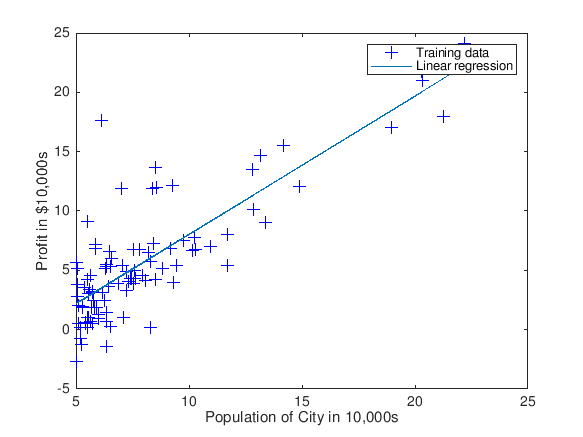


% Plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*theta, '-')
legend('Training data', 'Linear regression')
hold off % don't overlay any more plots on this figure

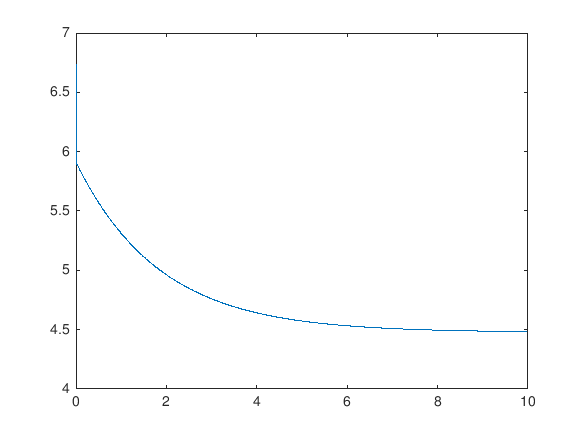


plot_iteration = linspace(0, 10, 1500);

plot(plot_iteration, J_history)
hold off;

% Predict values for population sizes of 35,000 and 70,000
predict1 = [1, 3.5] *theta;
fprintf('For population = 35,000, we predict a profit of %f\n', predict1*10000);

For population = 35,000, we predict a profit of 4519.767868


predict2 = [1, 7] * theta;
fprintf('For population = 70,000, we predict a profit of %f\n', predict2*10000);

For population = 70,000, we predict a profit of 45342.450129


    Note the way that the lines above use matrix multiplication, rather than explicit summation or looping, to calculate the predictions. This is an example of *code vectorization* in MATLAB. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

# 2.3 Debugging

Here are some things to keep in mind as you implement gradient descent: 

- MATLAB array indices start from one, not zero. If you're storing $\theta_0$ and $\theta_1$ in a vector called `theta`, the values will be `theta(1)` and `theta(2)`.

- If you are seeing many errors at runtime, inspect your matrix operations to make sure that you're adding and multiplying matrices of compatible dimensions. Printing the dimensions of variables with the `size` command will help you debug.

- By default, MATLAB interprets math operators to be matrix operators. This is a common source of size incompatibility errors. If you don't want matrix multiplication, you need to add the "dot" notation to specify this to MATLAB. For example, `A*B` does a matrix multiply, while `A.*B` does an element-wise multiplication.

# 2.4 Visualizing $J(\theta)$

To understand the cost function $J(\theta)$ better, you will now plot the cost over a 2-dimensional grid of $\theta_0$ and $\theta_1$ values. You will not need to code anything new for this part, but you should understand how the code you have written already is creating these images.

    In the next step, there is code set up to calculate $J(\theta)$ over a grid of values using the `computeCost` function that you wrote. 

% Visualizing J(theta_0, theta_1):
% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];    
	  J_vals(i,j) = computeCost(X, y, t);
    end
end

    After the code above is executed, you will have a 2-D array of $J(\theta)$ values. The code below will then use these values to produce surface and contour plots of $J(\theta)$ using the `surf` and `contour` commands. Run the code in this section now. The resulting plots should look something like the figure below.

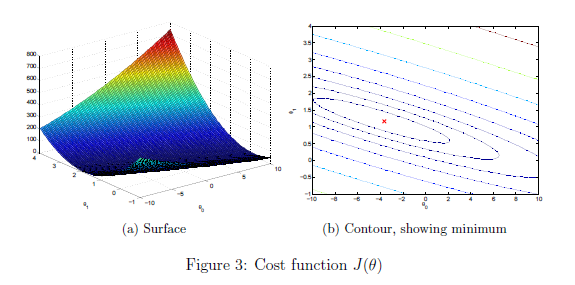

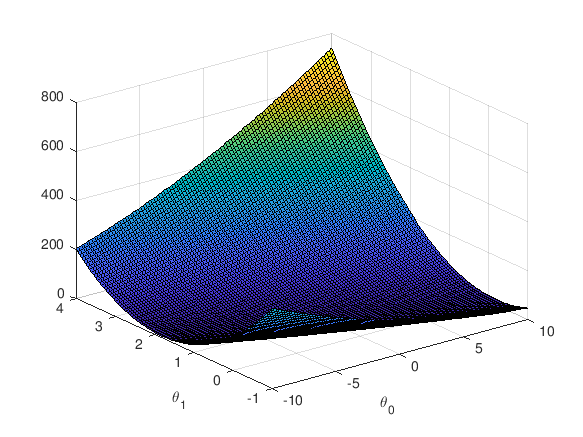

% Because of the way meshgrids work in the surf command, we need to 
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

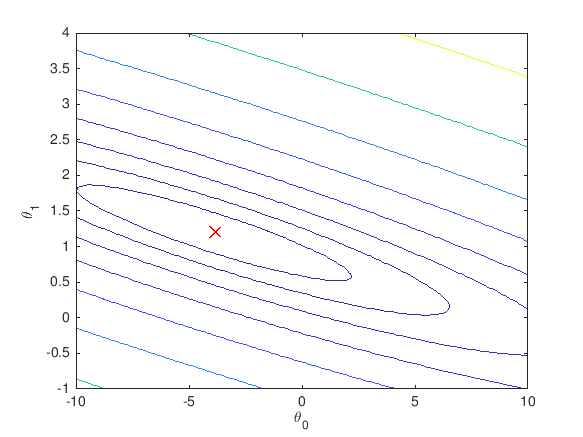


% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);

The purpose of these graphs is to show you that how $J(\theta)$ varies with changes in $\theta_0$ and $\theta_1$. The cost function $J(\theta)$ is bowl-shaped and has a global mininum. (This is easier to see in the contour plot than in the 3D surface plot). This minimum is the optimal point for $\theta_0$ and $\theta_1$, and each step of gradient descent moves closer to this point.

# Optional Exercises:

If you have successfully completed the material above, congratulations! You now understand linear regression and should able to start using it on your own datasets. For the rest of this programming exercise, we have included the following optional exercises. These exercises will help you gain a deeper understanding of the material, and if you are able to do so, we encourage you to complete them as well.

# 3. Linear regression with multiple variables

In this part, you will implement linear regression with multiple variables to predict the prices of houses. Suppose you are selling your house and you want to know what a good market price would be. One way to do this is to first collect information on recent houses sold and make a model of housing prices.

    The file `ex1data2.txt` contains a training set of housing prices in Portland, Oregon. The first column is the size of the house (in square feet), the second column is the number of bedrooms, and the third column is the price of the house. Run this section now to preview the data.

% Load Data
data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Print out some data points
% First 10 examples from the dataset
fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

 x = [2104 3], y = 399900 
 x = [1600 3], y = 329900 
 x = [2400 3], y = 369000 
 x = [1416 2], y = 232000 
 x = [3000 4], y = 539900 
 x = [1985 4], y = 299900 
 x = [1534 3], y = 314900 
 x = [1427 3], y = 198999 
 x = [1380 3], y = 212000 
 x = [1494 3], y = 242500 


The remainder of this script has been set up to help you step through this exercise.

# 3.1 Feature Normalization

This section of the script will start by loading and displaying some values from this dataset. By looking at the values, note that house sizes are about 1000 times the number of bedrooms. When features differ by orders of magnitude, first performing feature scaling can make gradient descent converge much more quickly.

    Your task here is to complete the code in `featureNormalize.m` to:

- Subtract the mean value of each feature from the dataset.

- After subtracting the mean, additionally scale (divide) the feature values by their respective "standard deviations".

The standard deviation is a way of measuring how much variation there is in the range of values of a particular feature (most data points will lie within $\pm 2$ standard deviations of the mean); this is an alternative to taking the range of values (*max - min*). In MATLAB, you can use the `std` function to compute the standard deviation. For example, inside `featureNormalize.m`, the quantity `X(:,1)` contains all the values of $x_1$ (house sizes) in the training set, so `std(X(:,1))` computes the standard deviation of the house sizes. At the time that `featureNormalize.m` is called, the extra column of 1's corresponding to $x_0 = 1$ has not yet been added to `X` (see the code below for details).

    You will do this for all the features and your code should work with datasets of all sizes (any number of features / examples). Note that each column of the matrix `X` corresponds to one feature. When you are finished with `featureNormailize.m`, run this section to normailze the features of the housing dataset.

% Scale features and set them to zero mean
[X, mu, sigma] = featureNormalize(X);

column = 2

**Implementation Note: **When normalizing the features, it is important to store the values used for normalization - the mean value and the standard deviation used for the computations. After learning the parameters from the model, we often want to predict the prices of houses we have not seen before. Given a new `x` value (living room area and number of bedrooms), we must first normalize `x` using the mean and standard deviation that we had previously computed from the training set.

Now that we have normailzed the features, we again add a column of ones corresponding to $\theta_0$ to the data matrix `X``.`

% Add intercept term to X
X = [ones(m, 1) X];

# 3.2 Gradient Descent

Previously, you implemented gradient descent on a univariate regression problem. The only difference now is that there is one more feature in the matrix `X`. The hypothesis function and the batch gradient descent update rule remain unchanged.

    You should complete the code in `computeCostMulti.m` and `gradientDescentMulti``.m `to implement the cost function and gradient descent for linear regression *with multiple variables*. If your code in the previous part (single variable) already supports multiple variables, you can use it here too.

Make sure your code supports any number of features and is well-vectorized. You can use the command `size(X,2)` to find out how many features are present in the dataset.

    We have provided you with the following starter code below that runs gradient descent with a particular learning rate (`alpha`). Your task is to first make sure that your functions `computeCost` and `gradientDescent` already work with this starter code and support multiple variables.  

**Implementation Note: **In the multivariate case, the cost function can also be written in the following vectorized form:


$$J(\theta)=\frac{1}{2m}\left(X\theta-\vec{y}\right)^T\left(X\theta-\vec{y}\right)$$


where


$$X=\left\lbrack \begin{array}{c}
{-\text{ }\left(x^{\left(1\right)} \right)}^T -\\
{-\text{ }\left(x^{\left(2\right)} \right)}^T -\\
\vdots \text{ }\\
{-\text{ }\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack \text{           }\vec{y} =\left\lbrack \begin{array}{c}
y^{\left(1\right)} \\
y^{\left(2\right)} \\
\vdots \text{ }\\
y^{\left(m\right)} 
\end{array}\right\rbrack$$


The vectorized version is efficient when you're working with numerical computing tools like MATLAB. If you are an expert with matrix operations, you can prove to yourself that the two forms are equivalent.

% Run gradient descent
% Choose some alpha value
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.

Error in gradientDescentMulti (line 21)
        temp_v(i) = theta(i) - alpha/m*sum((X*theta - y).*X(:,i));


% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

Finally, you should complete and run the code below to predict the price of a 1650 sq-ft, 3 br house using the value of `theta` obtained above. 

**Hint:** At prediction, make sure you do the same feature normalization. Recall that the first column of `X` is all ones. Thus, it does not need to be normalized.

% Estimate the price of a 1650 sq-ft, 3 br house
% ====================== YOUR CODE HERE ======================

ex_X = [1650, 3]

ex_X =         1650           3


ex_X_norm = zeros(1,2)

ex_X_norm =      0     0


for i = 1:2
     ex_X_norm(:,i) = (ex_X(:,i) - mu(i))./sigma(i);
end;
ex_X_norm = [1 ex_X_norm]

ex_X_norm =     1.0000   -0.4413   -0.2237


price = ex_X_norm * theta; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):
 $293081.464622

## **3.2.1 Optional (ungraded) exercise: Selecting learning rates**

In this part of the exercise, you will get to try out dierent learning rates for the dataset and find a learning rate that converges quickly. You can change the learning rate by modifying the code below and changing the part of the code that sets the learning rate.

    The code below will call your `gradientDescent` function and run gradient descent for about 50 iterations at the chosen learning rate. The function should also return the history of $J(\theta)$ values in a vector `J`. After the last iteration, the code plots the `J` values against the number of the iterations. If you picked a learning rate within a good range, your plot should look similar Figure 4 below. 

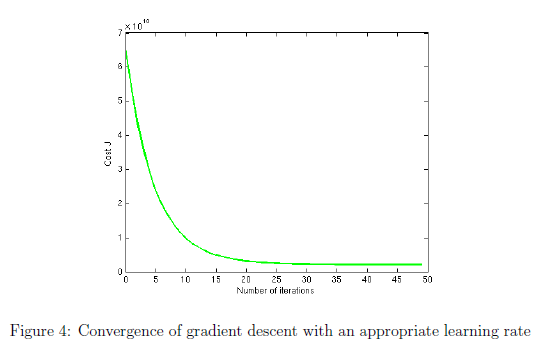

    If your graph looks very different, especially if your value of $J(\theta)$ increases or even blows up, use the control to adjust your learning rate and try again. We recommend trying values of the learning rate on a log-scale, at multiplicative steps of about 3 times the previous value (i.e., 0.3, 0.1, 0.03, 0.01 and so on). You may also want to adjust the number of iterations you are running if that will help you see the overall trend in the curve.

**Implementation Note:** If your learning rate is too large, $J(\theta)$ can diverge and 'blow up', resulting in values which are too large for computer calculations. In these situations, MATLAB will tend to return `NaNs`. `NaN` stands for 'not a number' and is often caused by undefined operations that involve $\pm \text{ }\infty$.

**MATLAB Tip:** To compare how different learning learning rates affect convergence, it's helpful to plot `J` for several learning rates on the same figure. In MATLAB, this can be done by performing gradient descent multiple times with a `hold on` command between plots. Make sure to use the `hold off` command when you are done plotting in that figure. Concretely, if you've tried three different values of `alpha` (you should probably try more values than this) and stored the costs in `J1`, `J2` and `J3`, you can use the following commands to plot them on the same figure:

    The final arguments `'b'`,`'r'`, and `'k``'` specify different colors for the plots. If desired, you can use this technique and adapt the code below to plot multiple convergence histories in the same plot. 

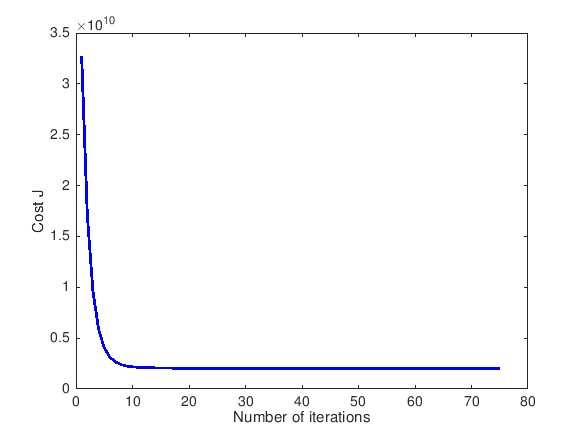

% Run gradient descent:
% Choose some alpha value
alpha = 0.3;
num_iters = 75;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[~, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Plot the convergence graph
plot(1:num_iters, J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');

Notice the changes in the convergence curves as the learning rate changes. With a small learning rate, you should find that gradient descent takes a very long time to converge to the optimal value. Conversely, with a large learning rate, gradient descent might not converge or might even diverge! 

    Using the best learning rate that you found, run the section of code below, which will run gradient descent until convergence to find the final values of $\theta$. Next, use this value of $\theta$ to predict the price of a house with 1650 square feet and 3 bedrooms. You will use value later to check your implementation of the normal equations. Don't forget to normalize your features when you make this prediction!

% Run gradient descent
% Replace the value of alpha below best alpha value you found above
alpha = 0.3;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f',theta(1),theta(2))

Theta computed from gradient descent:
340412.659574
110631.050279


% Estimate the price of a 1650 sq-ft, 3 br house. You can use the same
% code you entered ealier to predict the price
% ====================== YOUR CODE HERE ======================

ex_X = [1650, 3]

ex_X =         1650           3


ex_X_norm = zeros(1,2)

ex_X_norm =      0     0


for i = 1:2
     ex_X_norm(:,i) = (ex_X(:,i) - mu(i))./sigma(i);
end;
ex_X_norm = [1 ex_X_norm]

ex_X_norm =     1.0000   -0.4413   -0.2237


price = ex_X_norm * theta; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):
 $293081.464335

# 3.3 Normal Equations

In the lecture videos, you learned that the closed-form solution to linear regression is


$$\theta = \left(X^T X\right)^{-1} X^T \vec{y} $$


    Using this formula does not require any feature scaling, and you will get an exact solution in one calculation: there is no "loop until convergence" like in gradient descent.

    Complete the code in `normalEqn.m` to use the formula above to calculate $\theta$, then run the code in this section. Remember that while you don't need to scale your features, we still need to add a column of 1's to the `X` matrix to have an intercept term ($\theta_0$) . Note that the code below will add the column of 1's to `X` for you.

% Solve with normal equations:
% Load Data
data = csvread('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Add intercept term to X
X = [ones(m, 1) X];

% Calculate the parameters from the normal equation
theta = normalEqn(X, y);

% Display normal equation's result
fprintf('Theta computed from the normal equations:\n%f\n%f', theta(1),theta(2));

Theta computed from the normal equations:
89597.909543
139.210674

**Optional (ungraded) exercise: **Now, once you have found $\theta$ using this method, use it to make a price prediction for a 1650-square-foot house with 3 bedrooms. You should find that gives the same predicted price as the value you obtained using the model fit with gradient descent (in Section 3.2.1).

% Estimate the price of a 1650 sq-ft, 3 br house. 
% ====================== YOUR CODE HERE ======================

input = [1, 1650, 3];
price = input* theta  % Enter your price forumla here

price = 2.9308e+05


% ==========================================================
fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):
 $293081.464335

# Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

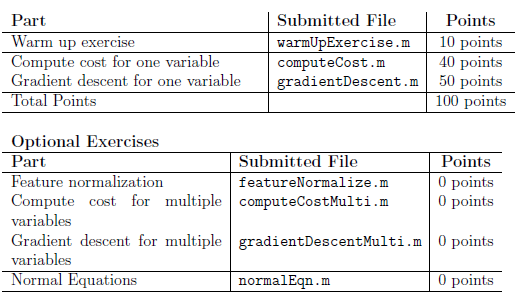

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.

**Define the cleanPath function used in the environment setup section:**

Do not modify the code below.

function [] = cleanPath() 
    % cleanPath() obtains the MATLAB search path and removes any other Machine Learning exercise folders. 
    % cleanPath() also prints out the current working directory and the files contained within for reference. 
    pth = strsplit(path,pathsep); % Obtain the search path 
    pth = ([pth{contains(pth,'machine-learning-ex')},{''}]); % Obtain any ML exercise folders that have been added to the path
    rmpath(pth{:}); % Remove these folders from the path
    pwd
    dir
end